# Tarea 01: Ajuste por mínimos cuadrados

Juan Diego Murcia Porras - jmurciap@unal.edu.co

Brayan Alejandro Romero Castro - brromeroc@unal.edu.co

Carlos Enrique Nosa Guzman - cnosa@unal.edu.co

### Ejercicio 1

La tabla 1.1 relaciona la cantidad de cierto aditivo a un barniz con el tiempo de secado del mismo. 

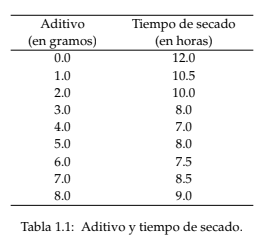

***a)*** Escriba el sistema de ecuaciones lineales asociado al problema de encontrar el polinomio de grado menor o igual a 2 que mejor ajusta por cuadrados mínimos los datos en la Tabla 1.1.

***Solución***

Suponiendo que tal polinomio es de la forma 

$$P(x)=ax^2+bx+c$$,

$a,b$ y $c$ deben satisfacer que 

$P(x_i)=a x_i^2+bx_i+c=y_i$, para $0\leq i \leq 8$,

donde los $x_i$ representan la cantidad de aditivo en la tabla, y los $y_i
$ su tiempo de secado. Así, obtenemos el sistema de ecuaciones

$\left \{ \begin{array}{rcl} 
a (0.0)^2+b(0.0)+c &=&12.0\\
 a (1.0)^2+b(1.0)+c& =&10.5 \\
a (2.0)^2+b(2.0)+c &=&10.0 \\ 
a (3.0)^2+b(3.0)+c &=&8.0 \\
a (4.0)^2+b(4.0)+c &=&7.0 \\
a (5.0)^2+b(5.0)+c &=&8.0 \\
a (6.0)^2+b(6.0)+c &=&7.5 \\
a (7.0)^2+b(7.0)+c &=&8.5 \\
a (8.0)^2+b(8.0)+c &=&9.0 \\
\end{array}  \right.$.

***b)*** Escriba un rutero de Matlab en el que se haga lo siguiente:

- Construya la matriz $\textbf{A}$ y parte derecha $\textbf{y}$ del sistema escrito por usted en 1.1

- Resuelva el sistema $\textbf{A}c=\textbf{y}$ en el sentido de los mínimos cuadrados.

- Grafique en un mismo gráfico los pares en la tabla y el ploinomio obtenido (evaluado en 100 puntos entre 0 y 8 y con ayuda de ployval).

***Solución***

Primero, definamos la matriz $\textbf{A}$y el vector $\textbf{y}$ pedidos

A=[0^2 0 1; 1^2 1 1; 2^2 2 1; 3^2 3 1; 4^2 4 1; 5^2 5 1; 6^2 6 1; 7^2 7 1; 8^2 8 1];
y=[12; 10.6; 10; 8; 7; 8; 7.5; 8.5; 9];

Ahora, resolvemos el sistema pedido en sentido de los mínimos cuadrados (como lo tiene Mathlab por defecto). Se muestra también el error cuadrático de tal estimación.

c=A\y

c =     0.1837
   -1.8576
   12.2230


Error_cuad=norm(y-A*c)

Error_cuad = 1.2669

Posteriormente, se grafican los pares de puntos y el polinomio obtenido.

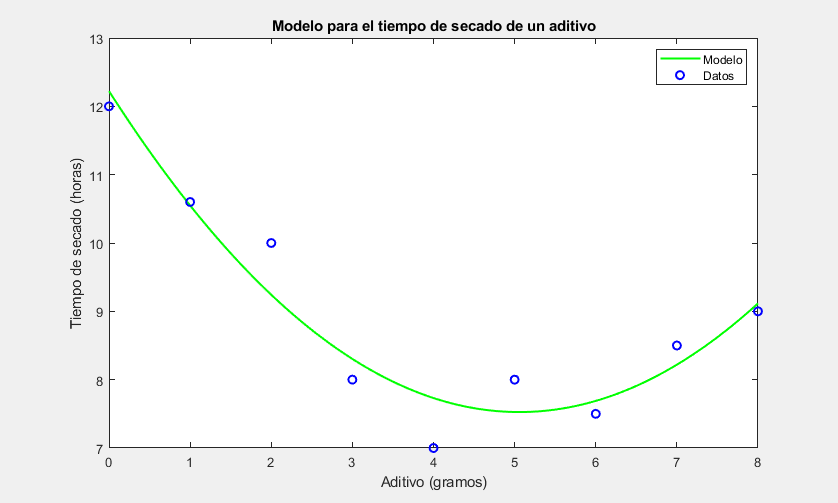

x=linspace(0,8,100);
plot(x,polyval(c,x),'g-',A(:,2),y,'ob','LineWidth',1.5)
box on
xlabel('Aditivo (gramos)')
ylabel('Tiempo de secado (horas)')
title('Modelo para el tiempo de secado de un aditivo')
legend('Modelo','Datos','Location','northeast');

- Basados en el polinomio resultante, ¿qué cantidad de aditivo resulta en tiempo mínimo de secado?¿cuál es el tiempo mínimo de secado?

***Solución***

 Como el polinomio es cuadrático y su amplitud es mayor a cero, basta con calcular el vértice del polinomio para resolver este problema. 

PM=[-c(2)/(2*c(1)); polyval(c,-c(2)/(2*c(1)))]

PM =     5.0572
    7.5259


Por lo tanto, según el modelo propuesto, 5.0572 gramos de aditivo resultan en un tiempo mínimo de secado de 7.5259 horas.

### Ejercicio 2

La misma idea del ajuste polinomial se puede aplicar para el ajuste de otro tipo de funciones $f$. Estas también satisfacen que:

$\sum_{i=1}^{m}|y_i - f(x_i)|^2$ sea mínima.

En las aguas de un lago hay tres clases de microorganismos provocadores de enfermedades. Se sabe que, en respuesta a un tratamiento aplicado a las aguas, los microorganimos están disminuyendo en forma exponencial de acuerdo al modelo:


$$p(t) = c_1 e^{-1.5 t}+ c_2 e^{-0.3t}+c_3 e^{-0.05t}, \quad t\geq 0,$$


donde $p(t)
$ da el número (en miles) de microorganismos. De una muestra de las aguas, en un laboratorio se obtuvieron los datos que se muestran en la tabla a continuación:

Tabla: Número de microorganismos de la muestra (en miles).

a) Escriba el sistema de ecuaciones lineales asociado al problema de encontrar la función exponencial $p(t)
$ que mejor ajusta por cuadrados mínimos los datos en la tabla.

b) Escriba un rutero en Matlab que haga lo siguiente:

- Construya la matriz $A$ y parte derecha y del sistema escrito por usted en la parte a).

- Resuelva el sistema $\textrm{Ay}=c$ en el sentido de los mínimos cuadrados.

- Grafique en un mismo gráfico los pares en la tabla y la función $p\left(t\right)$ obtenida.

- En base a la función obtenida, ¿cuál es el número de microorganismos que había en la muestra inicialmente? ¿y después de una hora y media? ¿y después de 5 horas y media?

***Solución***

***a)*** Utilizando los datos de la tabla vemos que queremos ajustar $c_1$, $c_2$, $c_3$ de tal foma que se tenga:


$$\left \{ \begin{array}{rcl} 
c_1 e^{-1.5(0.5)}+c_2 e^{-0.3(0.5)}+c_3e^{-0.05(0.5)} &=&7\\
c_1 e^{-1.5}+c_2e^{-0.3}+c_3e^{-0.05} &=& 5.2\\
c_1 e^{-1.5(2)}+c_2e^{-0.3(2)}+c_3e^{-0.05(2)} &=& 3.8 \\
c_1 e^{-1.5(3)}+c_2e^{-0.3(3)}+c_3e^{-0.05(3)} &=&3.2 \\
c_1 e^{-1.5(4)}+c_2e^{-0.3(4)}+c_3 e^{-0.05(4)}&=&2.5\\

\end{array}  \right.$$


***b)*** 

- Lo anterior puede ser desrito de forma matricial como:

$\left\lbrack \begin{array}{ccc}
e^{-1\ldotp 5\left(0\ldotp 5\right)}  & e^{-0\ldotp 3\left(0\ldotp 5\right)}  & e^{-0\ldotp 05\left(0\ldotp 5\right)} \\
e^{-1\ldotp 5}  & e^{-0\ldotp 3}  & e^{-0\ldotp 05} \\
e^{-1\ldotp 5\left(2\right)}  & e^{-0\ldotp 3\left(2\right)}  & e^{-0\ldotp 05\left(2\right)} \\
e^{-1\ldotp 5\left(3\right)}  & e^{-0\ldotp 3\left(3\right)}  & e^{-0\ldotp 05\left(3\right)} \\
e^{-1\ldotp 5\left(4\right)}  & e^{-0\ldotp 3\left(4\right)}  & e^{-0\ldotp 05\left(4\right)} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
7\\
5\ldotp 2\\
3\ldotp 8\\
3\ldotp 2\\
2\ldotp 5
\end{array}\right\rbrack$

- Utilizando  el comando  de matlab "\" podemos solucionar el anterior sistema, como se muestra en el siguiente codigo:

I2 = [0.5 1 2 3 4 ;7 5.2 3.8 3.2 2.5]; %Datos proporcionados
%Matriz y vector asociadas
A2 = transpose([exp(-1.5*I2(1,:)); exp(-0.3*I2(1,:)); exp(-0.05*I2(1,:))]);
y2 = transpose(I2(2,:));

% Sistema por mínimos cuadrados
c2 = A2\y2;

          Con el anterior código podemos ver que  la solución a nuestro sistema es:

$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
4\ldotp 9745\\
3\ldotp 0079\\
2\ldotp 0683
\end{array}\right\rbrack$

- Utilizando el comando plot, podemos Gráficar los datos anteriores, quedándonos:

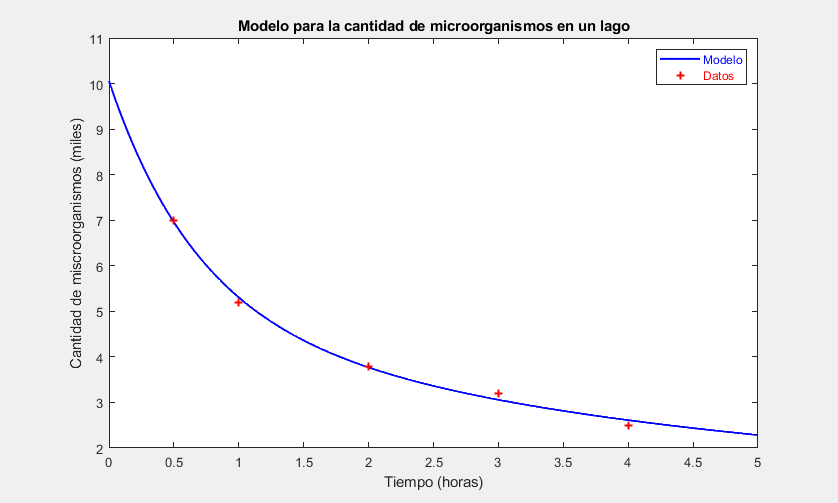

%Gráfica
X2 = 0:0.01:max(I2(1,:)+1); Y2= c2(1)*exp(-1.5*X2) + c2(2)*exp(-0.3*X2) + c2(3)*exp(-0.05*X2);
plot(X2,Y2,"b-",I2(1,:),I2(2,:),"r+",'LineWidth',1.5)
box on
xlabel('Tiempo (horas)')
ylabel('Cantidad de miscroorganismos (miles)')
title('Modelo para la cantidad de microorganismos en un lago')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')

- Los pronosticos son los siguientes según el código adjunto a este archivo:

 Microorganismos inicicales: 10.0508

Microorganismos en 1 hora y media: 4.3611

Microorganismos  en 5 horas y media: 2.1500

### Ejercicio 3

Las cifras de la tabla 1.3 son datos sobre el procentaje de llantas radiales producidas por cierto fabricante que aún pueden usarse después de recorrer cierto número de millas.

Se desea ajustar los datos de dicha tabla a los siguientes modelos en el sentido de los mínimos cuadrados:

$y_a(x)=\alpha \beta ^x$ e $y_b(x)=\alpha (100-x)10^{\beta x}$

Escriba un rutero en MATLAB que ejecute las siguientes tareas:

*a) *Determine los parámetros $\alpha$ y $\beta$ que ajustan ambos modelos a los datos de la tabla en el sentido de los mínimos cuadrados. Su programa debe mostrar estos parámetros.

**Solución: **Para el primer modelo, podemos aplicar la función $ln(\cdot)$ a ambos de la igualdad, y así obtener que 


$$ln(\alpha)+ln(\beta)\cdot x=ln(y_\alpha)$$


Por lo tanto, reemplazando cada dato $x_i$ por los miles de millas recorridas y $(y_\alpha)_i$ por el porcentaje útil ($1\leq i\leq 8$), y sustituyendo $c_1=ln(\alpha)$ y $c_2=ln(\beta)$, obtenemos que


$$\left \{ \begin{array}{rcl} 
c_1+1c_2  &=& ln(99)\\
c_1+2c_2  &=& ln(95)\\
c_1+5c_2  &=& ln(85)\\
c_1+15c_2  &=& ln(15)\\
c_1+25c_2  &=& ln(30)\\
c_1+30c_2  &=& ln(24)\\
c_1+35c_2  &=& ln(20)\\
c_1+40c_2 &=& ln(15)
\end{array}  \right.$$


O, de otra forma, el sistema dado por


$$\textbf{A}c=\textbf{y} \rightarrow$$

$$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2\\
1 & 5\\
1 & 15\\
1 & 25\\
1 & 30\\
1 & 35\\
1 & 40
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \left(99\right)\\
\ln \left(95\right)\\
\ln \left(85\right)\\
\ln \left(15\right)\\
\ln \left(30\right)\\
\ln \left(24\right)\\
\ln \left(20\right)\\
\ln \left(15\right)
\end{array}\right\rbrack$$


Resolviéndolo en MATLAB,

A1=[[1 1 1 1 1 1 1 1]' [1 2 5 15 25 30 35 40]'];
y1=log([99 95 85 15 30 24 20 15]');
x1=A1\y1;
alpha1=exp(x1(1))

alpha1 = 85.2017

beta1=exp(x1(2))

beta1 = 0.9554

Por otro lado, para la segunda función planteada, aplicando la función $ln(\cdot)$ a ambos lados, obtenemos que 


$$ln(\alpha)+ln(100-x)+\beta \cdot ln (10) \cdot x=ln(y_b)$$


O, de otra manera,


$$ln(\alpha)+x\cdot ln (10) \cdot \beta=ln(y_b)-ln(100-x)$$


Reemplazando los datos de la tabla de manera similar a con $y_a$, y realizando las sustituciones $c_1=ln(\alpha)$ y $c_1=\beta$, obtenemos el sistema


$$\left \{ \begin{array}{rcl} 
c_1+(1)\cdot ln(10)\cdot c_2  &=& ln(99)-ln(100-1)\\
c_1+(2)\cdot ln(10)\cdot c_2  &=& ln(95)-ln(100-2)\\
c_1+(5)\cdot ln(10)\cdot c_2  &=& ln(85)-ln(100-5)\\
c_1+(15)\cdot ln(10)\cdot c_2  &=& ln(55)-ln(100-15)\\
c_1+(25)\cdot ln(10)\cdot c_2  &=& ln(30)-ln(100-25)\\
c_1+(30)\cdot ln(10)\cdot c_2  &=& ln(24)-ln(100-30)\\
c_1+(35)\cdot ln(10)\cdot c_2  &=& ln(20)-ln(100-35)\\
c_1+(40)\cdot ln(10)\cdot c_2  &=& ln(15)-ln(100-40)\\
\end{array}  \right.$$


Realizando un procedimiento análogo al anterior, resolvemos el sistema en cuestión.

A2=[[1 1 1 1 1 1 1 1]' log(10)*[1 2 5 15 25 30 35 40]'];
y2=log([99 95 85 55 30 24 20 15]')-log([100-1 100-2 100-5 100-15 100-25 100-30 100-35 100-40]');
x2=A2\y2;
alpha2=exp(x2(1))

alpha2 = 1.0525

beta2=x2(2)

beta2 = -0.0157

b) Para ambos modelos, muestre $||\textbf{b}-\textbf{A}x||_2$ del sistema $\textbf{A}x=\textbf{b}$ que su programa resuelve.

**Solución: **Calculemos ambas normas.

v1=norm(y1-A1*x1)

v1 = 1.1343

v2=norm(y2-A2*x2)

v2 = 0.1026

Por lo tanto, el mejor modelo (según la norma euclidea) es el segundo.

c) Dibuje en un mismo gráfico los datos de la tabla y ambos modelos ajustados.

**Solución:**

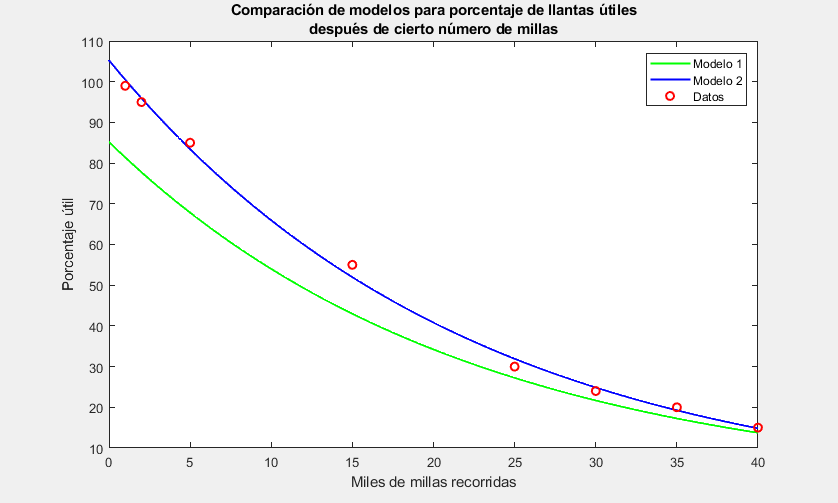

x=linspace(0,40,1000);
I1=A1(:,2);
I2=[99 95 85 55 30 24 20 15]';
plot(x, alpha1* beta1.^(x),'g-',x, alpha2.*(100-x).*10.^(beta2*x),'b-', I1, I2,'or','LineWidth',1.5)
xlabel('Miles de millas recorridas')
ylabel('Porcentaje útil')
title({'Comparación de modelos para porcentaje de llantas útiles';'después de cierto número de millas'})
legend('Modelo 1','Modelo 2','Datos','Location','northeast');

d) Con el mejor modelo, estime qué porcentaje de las llantas radiales del fabricante durarán 45000 millas y 50000 millas. Su programa debe mostrar estas estimaciones.

**Solución: **Usando el segundo modelo, estimemos ambos valores.

est_1=alpha2.*(100-45).*10.^(beta2*45)

est_1 = 11.3532

est_2=alpha2.*(100-50).*10.^(beta2*50)

est_2 = 8.6123

Por ende, con este modelo se estima que aproximadamente el 11.3% de las llantas radiales durarán 45000 millas, y el 8.61% durarán 50000.

### Ejercicio 4

Para estimar la cantidad de vitamina A requerida para mantener el peso se dió a ratas de laboratorio una dieta básica exenta de vitamina A y se les administró raciones controladas de vitamina A en forma de tabletas. La tabla muestra la relación entre la cantidad de vitamina A administrada y el aumento de peso de las ratas.

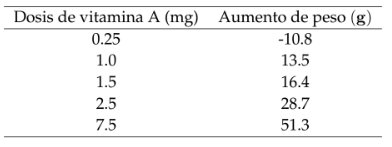

Tabla: Aumento de peso de las ratas al administrar vitamina A.

- Escriba un rutero MATLAB que,

Aumento de peso = $a+b\;\log_{10}$(Dosis de vitamina A), $a, b \in \mathbb{R}$

             que mejor ajusta por cuadrados mínimos los datos dados

- Grafique en un mismo gráfico los pares en la tabla y la función obtenida.

- Basado en la función obtenida, ¿qué cantidad de vitamina A es requerida para no aumentar de peso?

***Solución***

- Notemos que el sistema que tenemos que resolver (en forma matricial), por minimos cuadrados es el siguiente:


$$\left\lbrack \begin{array}{cc}
1 & \log_{10} \left(0\ldotp 25\right)\\
1 & \log_{10} \left(1\ldotp 0\right)\\
1 & \log_{10} \left(1\ldotp 5\right)\\
1 & \log_{10} \left(2\ldotp 5\right)\\
1 & \log_{10} \left(7\ldotp 5\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-10\ldotp 8\\
13\ldotp 5\\
16\ldotp 4\\
28\ldotp 7\\
51\ldotp 3
\end{array}\right\rbrack$$


Escrito como un rutero sería


I4 = [0.25 1 1.5 2.5 7.5; -10.8 13.5 16.4 28.7 51.3]; %Datos proporcionados
%Matriz y vector asociadas
A4 = transpose([ones(1,5);log10(I4(1,:))]);
y4 = transpose(I4(2,:));

- Solucionamos este sistema utilizando mldivide, que halla la solución por minimos cuadrados

c4 = mldivide(A4'*A4,A4'*y4);

Dándonos la solución:


$$\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
12\ldotp 7623\\
41\ldotp 6611
\end{array}\right\rbrack$$


- Utilizando el comando plot, podemos Gráficar los datos anteriores, quedandonos:

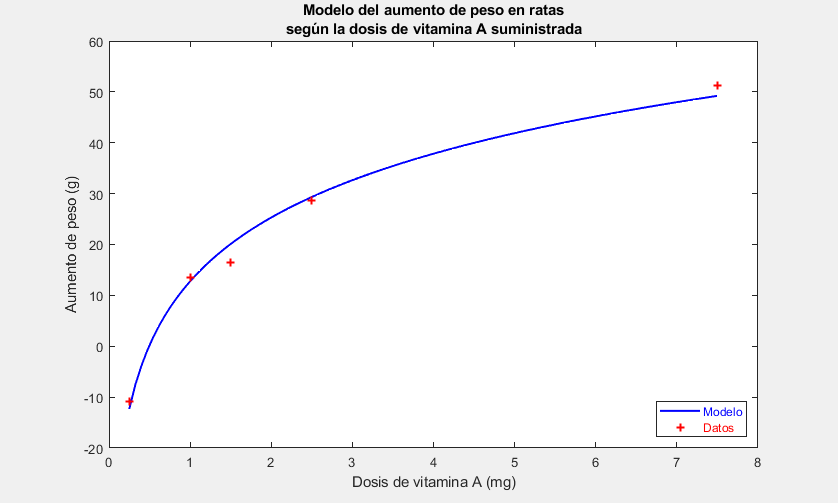

%Gráfica
X4 = 0.25:7.25/100:7.5; Y4= c4(1) + c4(2)*log10(X4);
plot(X4,Y4,"b-",I4(1,:),I4(2,:),"r+",'LineWidth',1.5)
box on
xlabel('Dosis de vitamina A (mg)')
ylabel('Aumento de peso (g)')
title({'Modelo del aumento de peso en ratas';'según la dosis de vitamina A suministrada'})
[a,b]=legend('Modelo','Datos','Location','southeast');
set(b(1),'Color','b')
set(b(2),'Color','r')

### Ejercicio 5

La tabla muestra la concentración de iones $n$ como una función del tiempo transcurrido después de haber apagado a un agente de ionización. Se sabe que se cumple la siguiente relación entre la concentración de iones y el tiempo


$$n=\frac{n_0}{1+n_0\alpha t}$$


donde $n_0$ es la concentración inicial de iones y $\alpha$, el coeficiente de recombinación.

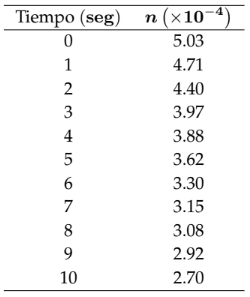

***a)*** Muestre que existe una relación lineal entre $n^{-1}$ y $t$.

***Demostración***

Tenemos que 


$$1+n_0\alpha t=\frac{n_0}{n}$$


y, por consiguiente, 


$$1=n_0\cdot (n^{-1})- n_0 \alpha \cdot (t)$$


Por lo tanto, existe una relación lineal entre ambas variables.

***b) ***Encuentre la función (1) que mejor ajusta por cuadrados mínimos a los datos en la tabla. Escriba las aproximaciones de $n_0$ y $\alpha$ obtenidas.

***Solución***

Utilizando la demostración del literal a), podemos concluir que 


$$\frac{1}{n_0}+\alpha t= \frac{1}{n}$$


Utilizando los datos de la tabla, $c_1=\frac{1}{n_0}$ y $c_2=\alpha$, obtenemos el sistema


$$\left \{ \begin{array}{rcl} 
c_1+0 c_2 &=& \frac{1}{5.03}\\
c_1+1 c_2 &=& \frac{1}{4.71}\\
c_1+2 c_2 &=& \frac{1}{4.40}\\
c_1+3 c_2 &=& \frac{1}{3.97}\\
c_1+4 c_2 &=& \frac{1}{3.88}\\
c_1+5 c_2 &=& \frac{1}{3.62}\\ 
c_1+6 c_2 &=& \frac{1}{3.30}\\ 
c_1+7 c_2 &=& \frac{1}{3.15}\\ 
c_1+8 c_2 &=& \frac{1}{3.08}\\ 
c_1+9 c_2 &=& \frac{1}{2.92}\\ 
c_1+10 c_2 &=& \frac{1}{2.70}\\ 
\end{array}  \right. $$


Resolvamos este sistema en MATLAB.

A=[[1 1 1 1 1 1 1 1 1 1 1]' [0 1 2 3 4 5 6 7 8 9 10]'];
y=1./[5.03 4.71 4.4 3.97 3.88 3.62 3.3 3.15 3.08 2.92 2.7]';
x=A\y;
Error_cuadratico=norm(y-A*x)

Error_cuadratico = 0.0154

n_0=1/x(1)

n_0 = 5.0956

alpha=x(2)

alpha = 0.0168

Por lo tanto, usando el método de mínimos cuadrados, $n_0=5.096$ y $\alpha=0.017$. El error cuadrático de la solución del sistema lineal asociado es de $0.0154$.

c) Grafique los pares ordenados en la tabla y la función $n$ obtenida (evaluada en 110 puntos de 0 a 10).

***Solución***

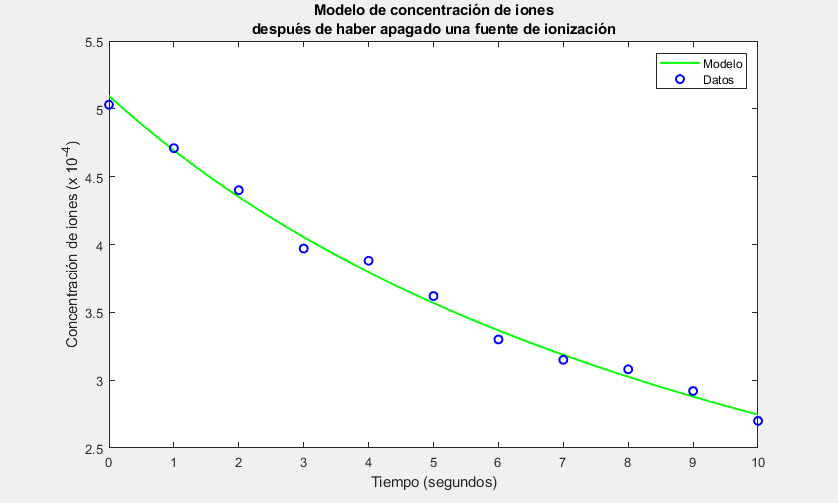

x=linspace(0,10,110);
I1=A(:,2);
I2=[5.03 4.71 4.4 3.97 3.88 3.62 3.3 3.15 3.08 2.92 2.7]';
plot(x,n_0./(1+(n_0.*alpha.*x)),'g-',I1,I2,'ob','LineWidth',1.5)
xlabel('Tiempo (segundos)')
ylabel('Concentración de iones (x 10^{-4})')
title({'Modelo de concentración de iones'; 'después de haber apagado una fuente de ionización'})
[a,b]=legend('Modelo','Datos','Location','northeast');

### Ejercicio 6: La genialidad de Leonardo Da Vinci

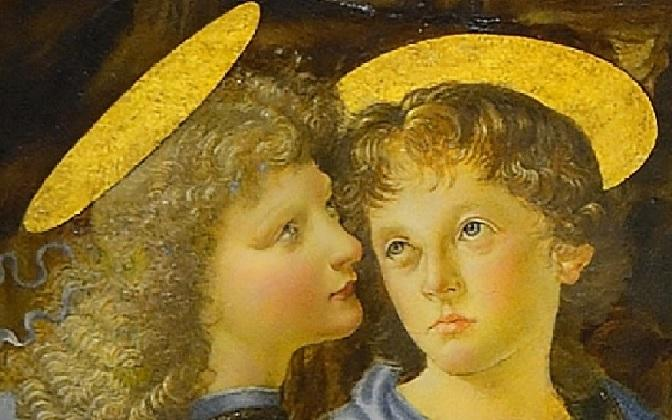

Figura 1. Fragmento de la pintura *Bautismo de Cristo.*

El objetivo en este ejercicio es conocer si el pupilo superó al maestro. En las pinturas medievales, las personas santas se distinguían con una aureola circular detrás de la cabeza. Durante el Renacimiento, el progreso de la ciencia transformó estas aureolas en elipses. Esto nos da la ocasión para presentar la precisión de una de las pinturas de Leonardo bajo investigación científica. Elegimos la pintura El Bautismo de Cristo de 1472, donde el joven alumno Leonardo añadió un ángel adicional (ángel a la izquierda) a una pintura de su maestro Andrea del Verrocchio (ver la Figura).

***Solución***

Con el fin de obtener datos de la aureola izquierda, se seleccionaron manualmente 22 puntos del borde de la figura geométrica con ayuda del código mostrado a continuación.

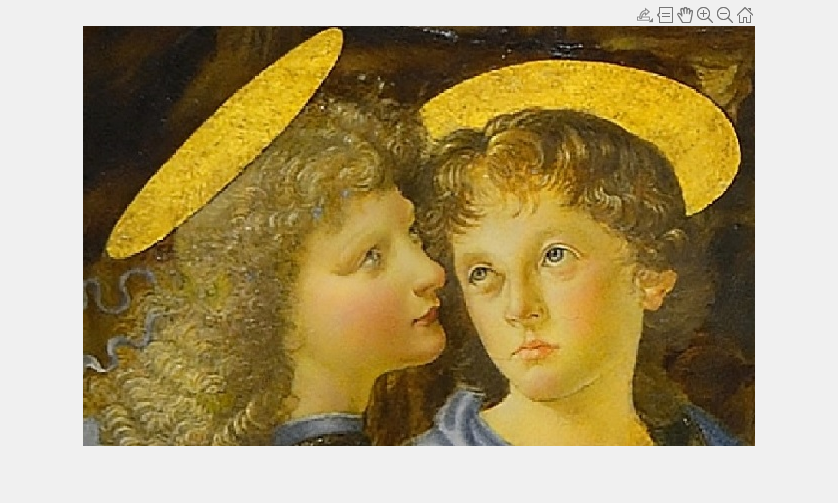

imshow('angeles.jpg')
[x1,y1] = ginput(22);

Luego de esto, se propone el modelo

$Ax^2+By^2+Cxy+Dx+Ey=10000$,

con parámetros desconocidos $A,B,C,D$ y $E$. La elección de este modelo se hace con el objetivo de expresar una cónica de manera general, en donde el término $\textrm{xy}$ tiene el fin de capturar la inclinación del objeto respecto a los ejes cartesianos y el término independiente $10000$ se escoge para 'regular' los datos de tal forma que los parámetros sean números en un rango 'cómodo' para graficar (Nota: La elección de la constante $10000$ se realizó dado que los datos tomados son de orden $10^{2}$ y en la matriz se convierten en datos de orden de $10^4 = 10000$. Esto ayuda a que los parámetros calculados por el método de los mínimos cuadrados estén en un rango en el que no se pierdan muchas cifras significativas).

Considerando el modelo planteado, se construye la matriz,

Eleft = [x1.*x1 y1.*y1 x1.*y1 x1 y1];

y se procede a la solución del sistema $E_{left}\cdot c = \mathbf{10000}$, en donde $\mathbf{10000}$ representa el vector columna de tamaño $22\times 1$con todas sus entradas iguales a $10000$,

cleft = mldivide(Eleft'*Eleft,10000*Eleft'*ones(22,1));

Al realizar es proceso obtenemos que

fprintf('%g ',cleft)

-0.149744 -0.16067 -0.289649 77.384 79.7377 

en donde $c_{left}=(A,B,C,D,E)^{T}$.

Si graficamos los datos obtenidos versus la gráfica de la elipse hallada por el método de los mínimos cuadrados obtenemos lo siguiente,

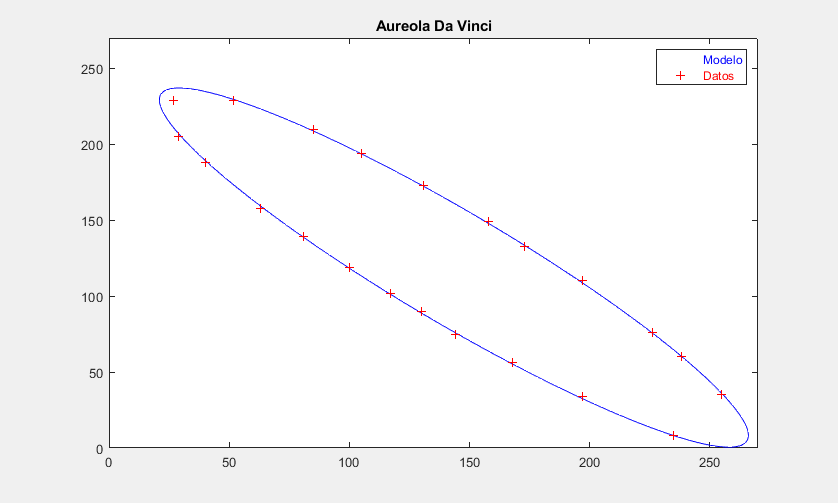

fleft = @(x,y) cleft(1)*x.^2+cleft(2)*y.^2+cleft(3)*x.*y+cleft(4)*x+cleft(5)*y-10000;
fimplicit(fleft,[0 270],'b-')
hold on
plot(x1,y1,'r+')
title('Aureola Da Vinci')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')
hold off

Ahora, para realizar el cálculo del error hallamos la norma del vector $ \mathbf{10000}- E_{left}\cdot c_{left}$

norm(10000*ones(22,1)-Eleft*cleft,2) %Norma matricial euclidiana

ans = 71.5672

Una vez hecho el proceso con la aureola izquierda, se repiten los mismos pasos con la aureola derecha. Se seleccionan manualmente 22 puntos del borde de la figura geométrica con ayuda del  siguiente código.

imshow('angeles.jpg')
[x2,y2] = ginput(22);

Se plantea el mismo modelo y se construye la matriz adecuada.

Eright = [x2.*x2 y2.*y2 x2.*y2 x2 y2];

El sistema de mínimos cuadrados es aplicado de la misma manera que en el caso anterior.

cright = mldivide(Eright'*Eright,10000*Eright'*ones(22,1));

Una vez terminado el cálculo, se obtiene:

fprintf('%g ',cright)

-0.038034 -0.133736 0.00171306 36.9678 32.8365 

en donde $c_{right}=(A,B,C,D,E)^{T}$.

Para hacer una primera comparación, se realiza la gráfica de datos versus el modelo obtenido.

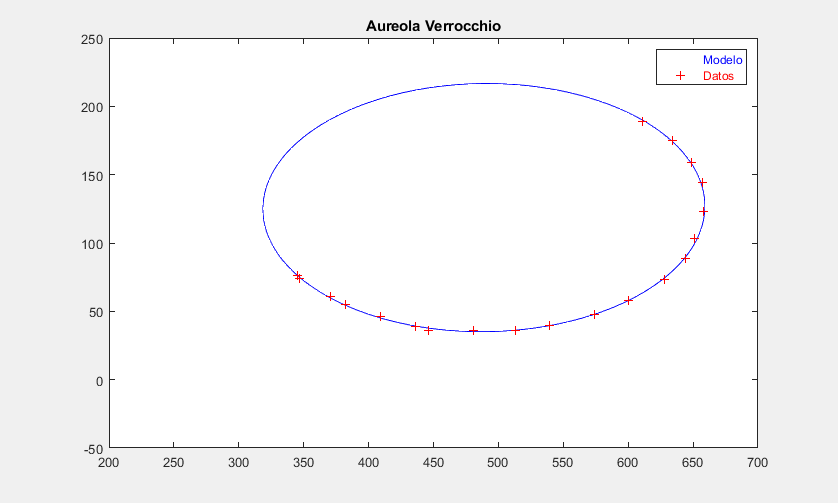

fright = @(x,y) cright(1)*x.^2+cright(2)*y.^2+cright(3)*x.*y+ cright(4)*x+cright(5)*y-10000;
fimplicit(fright,[200 700 -50 250],'b-')
hold on
plot(x2,y2,'r+')
title('Aureola Verrocchio')
[a,b]=legend('Modelo','Datos','Location','northeast');
set(b(1),'Color','b')
set(b(2),'Color','r')
hold off

Finalmente, se obtiene el error entre el modelo y los datos calculados.

norm(10000*ones(22,1)-Eright*cright,2) %Norma matricial euclidiana

ans = 73.8392

En conclusión, la aureola izquierda se ajusta mejor a una elipse que la aureola derecha (revise el código a continuación), esto quiere decir en términos prácticos que Leonardo Da Vinci superó a su maestro Andrea del Verrochio (considerando el modelo propuesto de la elipse, el método de mínimos cuadrados y la toma de datos como adecuados para la solución del problema).

% ¿Da Vinci superó a Verrochio?
% Si (1)
% No (0)
norm(10000*ones(22,1)-Eleft*cleft,2)<norm(10000*ones(22,1)-Eright*cright,2)

ans = logical
   1
